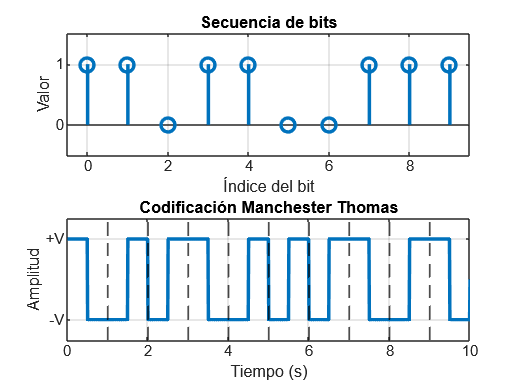

clc;    
clear;  
close all;

% --------------------------
% 1. Generación de la data
% --------------------------
bit_seq = randi([0 1], 1, 10); % Secuencia aleatoria de 10 bits
bit_duracion = 1;  % Duración de cada bit en segundos
fs = 100;  % Frecuencia de muestreo
t = 0:1/fs:length(bit_seq)*bit_duracion;  

% Inicializar señal
signal = zeros(size(t));

% -------------------------------
% 2. Construcción de la señal Manchester Thomas
% -------------------------------
samples_per_bit = fs * bit_duracion; % Cantidad de muestras por bit
prev_level = 1; % Iniciamos con nivel alto

index = 1;
for i = 1:length(bit_seq)
    mid = index + samples_per_bit/2 - 1; % Punto medio del bit
    
    if bit_seq(i) == 1
        % Bit 1: Mantiene nivel hasta la mitad, luego cambia
        signal(index:mid) = prev_level;
        signal(mid+1:index+samples_per_bit-1) = -prev_level;
    else
        % Bit 0: Cambio al inicio, luego mantiene
        prev_level = -prev_level;
        signal(index:mid) = prev_level;
        signal(mid+1:index+samples_per_bit-1) = -prev_level;
    end
    
    prev_level = signal(mid+1); % Actualizar nivel previo
    index = index + samples_per_bit;  % Avanzar al siguiente bit
end

% -------------------------
% 3. Creación de la figura
% -------------------------
figure;

% -------------------------------
% Subplot 1: Representación de bits
% -------------------------------
subplot(2,1,1); 
stem(0:length(bit_seq)-1, bit_seq, 'LineWidth', 2, 'MarkerSize', 8); 
ylim([-0.5 1.5]); 
xlim([-0.5 length(bit_seq)-0.5]);  
yticks([0 1]); 
yticklabels({'0', '1'}); 
xlabel('Índice del bit'); 
ylabel('Valor');  
title('Secuencia de bits');  
grid on; 

% -------------------------------
% Subplot 2: Señal Manchester Thomas
% -------------------------------
subplot(2,1,2);  
plot(t, signal, 'LineWidth', 2);
ylim([-1.5 1.5]); 
xlim([0 length(bit_seq)*bit_duracion]);  
yticks([-1 1]); 
yticklabels({'-V', '+V'});  
xlabel('Tiempo (s)'); 
ylabel('Amplitud');  
title('Codificación Manchester Thomas');
grid on; 
hold on;

% Líneas verticales para separar los bits
for i = 1:length(bit_seq)-1
    xline(i*bit_duracion, '--k', 'LineWidth', 1);  
end

hold off;